clf;
homedir='/Users/editabulovaite/Documents/PhD_Year3/Data';

dirNameForFileName=strrep(homedir,'/','-slash-'); %if the dirName is in fact a path containing several directories, we substitute any / to the string -slash- as / is not a valid file name character
dirNameForFileName=strrep(dirNameForFileName,'\','-slash-');

delimiter='\t';

data=dir('Lifespan_halflife_26032021.csv');
data = readtable(data.name);


halflife = data(1:110,4);
halflife = table2array(halflife);
halflife1 = halflife';


d=bsxfun(@minus,halflife,halflife1);
sigma = std(d,0,'all')

sigma = 4.6940

sim_score = exp(-(d.^2/2*sigma^2));

writematrix(sim_score,'Similarity_score_18M')

h=heatmap(sim_score,"GridVisible","off")

h =   HeatmapChart with properties:

        XData: {110×1 cell}
        YData: {110×1 cell}
    ColorData: [110×110 double]

  Show all properties


h.Colormap = jet

h =   HeatmapChart with properties:

        XData: {110×1 cell}
        YData: {110×1 cell}
    ColorData: [110×110 double]

  Show all properties


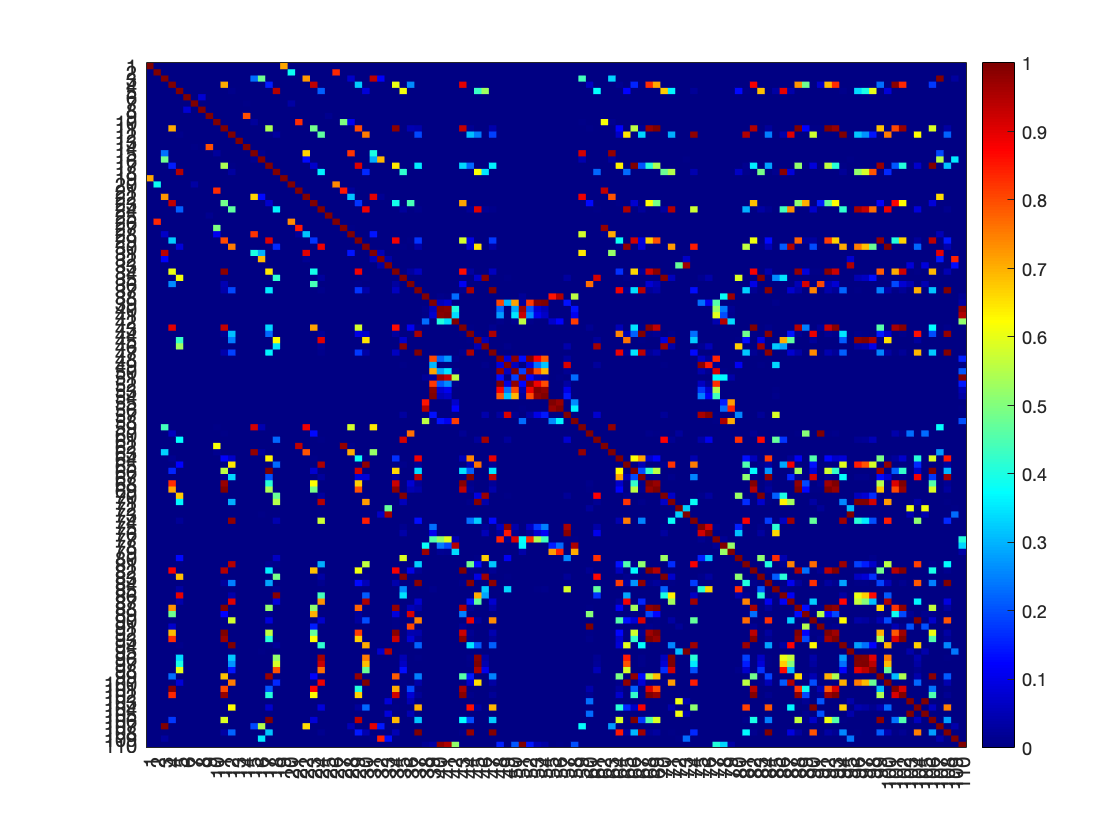


saveas(gcf,['Halflife_similarity_matrix_18M_turnover_study'],'png')%change the name as you wish
saveas(gcf,['Halflife_similarity_matrix_18M_turnover_study'],'fig')
saveas(gcf,['Halflife_similarity_matrix_18M_turnover_study'],'eps')